% crest factor optimization comparison and final algorithm
% (c) Mess- und Sensortechnik, TU Chemnitz
% Author: Ahmed Yahia Kallel

## laundry

clc
clf
% close all
clear

diary('deblur')

## Scenario

GPU = 1; % disable if GPU is not Nvidia


% RNGN = 1024;
% rng(RNGN); %uncomment to make pseudo-random (repeatable results)



MAX_ITER = 1000; % maximum opt iterations
N = 4096; %number of samples
Fs = 5e6; Ts = 1/Fs; %sampling frequency
fmax = 10e3; %max f
fmin = 1e3; % min f
nfreqs = 20; % number of frequencies

## Generate time vector & frequency vector, optimize frequency vector

t = [0:N-1]*Ts;
Fbins = [0:N-1]/N*Fs;
f = logspace(log10(fmin),log10(fmax),nfreqs).';


%Frequency bins optimization
fbins = Fs * [0:numel(t)-1]./numel(t);
[~, f_freqbins_map] = min(abs(f'-repmat(fbins,nfreqs,1)'));
forg = f;
f = fbins(f_freqbins_map); f = unique(f); f = f(:);
f_freqbins_map = unique(f_freqbins_map);
nfreqs = numel(f);

fprintf('Sampling Frequency: %2.3e Hz\n', Fs);

Sampling Frequency: 5.000e+06 Hz


fprintf('Requested Frequency range %2.3e Hz - %2.3e Hz, Nfreqs = %d\n', fmin,fmax,numel(forg));

Requested Frequency range 1.000e+03 Hz - 1.000e+04 Hz, Nfreqs = 20


fprintf('Actual Frequency range %2.3e Hz - %2.3e Hz, Nfreqs = %d\n', min(f),max(f),nfreqs);

Actual Frequency range 1.221e+03 Hz - 9.766e+03 Hz, Nfreqs = 8


fprintf('Time %2.3f \n', max(t));

Time 0.001 



fprintf('Scenario - RNG - MAX ITER %d \n', MAX_ITER);

Scenario - RNG - MAX ITER 1000 


## generate signal

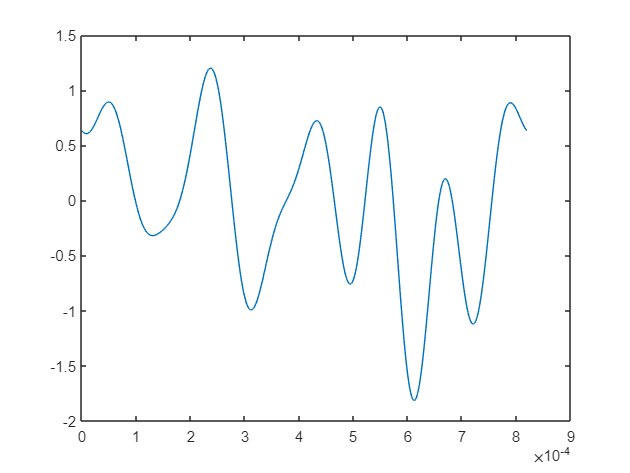

% Amplitudes & phases
A = ones(nfreqs,1)  / sqrt(nfreqs);
Phi = rand(size(A))*2*pi;


oPhi = Phi;
Mx_t = repmat(t,nfreqs,1);
S = A.*cos(2.*pi.*f.*Mx_t+Phi);
s = sum(S,1);


plot(t,s);

fprintf('Initial Crest factor: %2.3f\n', peak2rms(s));

Initial Crest factor: 2.567




Phi = oPhi;
oS = s;
cf_deblur_v2;

End of Round 40, best cf: 1.508
End of Round 39, best cf: 1.403
End of Round 38, best cf: 1.403
End of Round 37, best cf: 1.403
End of Round 36, best cf: 1.403
End of Round 36, best cf: 1.403


peak2rms(s)

ans = 1.4041

Phi = deblurL2p.bestphi;

S = A.*cos(2.*pi.*f.*Mx_t+Phi);
s = sum(S,1);

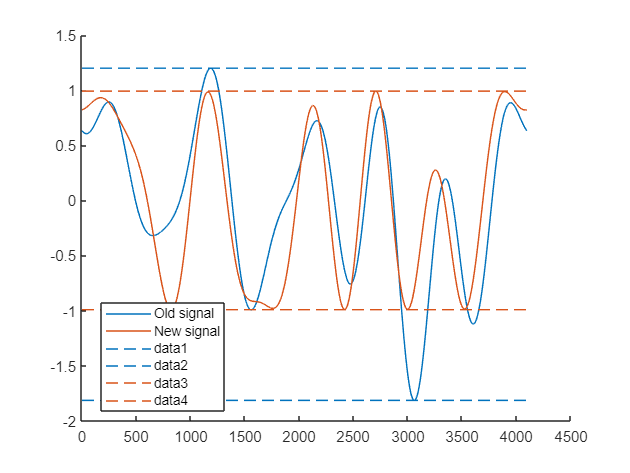

clf
hold on
p1= plot(oS,'DisplayName','Old signal');
p2 = plot(s,'DisplayName','New signal');

plot([1 numel(oS)], [min(oS) min(oS)], '--','Color',p1.Color)
plot([1 numel(oS)], [max(oS) max(oS)], '--','Color',p1.Color)
plot([1 numel(oS)], [min(s) min(s)], '--','Color',p2.Color)
plot([1 numel(oS)], [max(s) max(s)], '--','Color',p2.Color)
legend('location','best')


t = table(f,A,Phi)

t = 8×3 table
      f          A          Phi   
    ______    _______    _________

    1220.7    0.35355    -0.062624
    2441.4    0.35355     -0.65595
    3662.1    0.35355      0.38882
    4882.8    0.35355     -0.60656
    6103.5    0.35355      -2.9642
    7324.2    0.35355       1.0178
    8544.9    0.35355       2.2062
    9765.6    0.35355      -1.7299


# **Generate signal**

s_normal = s / max(abs(s));

signal_stm32 = floor((s_normal + 1)/2 * 4095);

fprintf('#define SIZE_F %d\n',numel(f));

#define SIZE_F 8



fprintf('uint32_t signal[SIGNAL_LENGTH] = {')

uint32_t signal[SIGNAL_LENGTH] = {

fprintf('%d, ', signal_stm32(1:end-1))

3745, 3745, 3746, 3746, 3747, 3748, 3748, 3749, 3750, 3751, 3752, 3752, 3753, 3754, 3755, 3756, 3757, 3758, 3759, 3760, 3761, 3763, 3764, 3765, 3766, 3767, 3769, 3770, 3771, 3773, 3774, 3775, 3777, 3778, 3780, 3781, 3783, 3784, 3786, 3787, 3789, 3790, 3792, 3794, 3795, 3797, 3798, 3800, 3802, 3804, 3805, 3807, 3809, 3811, 3812, 3814, 3816, 3818, 3820, 3821, 3823, 3825, 3827, 3829, 3831, 3832, 3834, 3836, 3838, 3840, 3842, 3844, 3846, 3848, 3850, 3851, 3853, 3855, 3857, 3859, 3861, 3863, 3865, 3867, 3869, 3870, 3872, 3874, 3876, 3878, 3880, 3882, 3884, 3885, 3887, 3889, 3891, 3893, 3895, 3896, 3898, 3900, 3902, 3903, 3905, 3907, 3909, 3910, 3912, 3914, 3915, 3917, 3918, 3920, 3922, 3923, 3925, 3926, 3928, 3929, 3931, 3932, 3934, 3935, 3936, 3938, 3939, 3940, 3942, 3943, 3944, 3945, 3947, 3948, 3949, 3950, 3951, 3952, 3953, 3954, 3955, 3956, 3957, 3958, 3959, 3960, 3961, 3962, 3962, 3963, 3964, 3964, 3965, 3966, 3966, 3967, 3967, 3968, 3968, 3969, 3969, 3970, 3970, 3970, 3971, 3971, 3971

fprintf('%d', signal_stm32(end))

3744

fprintf('};\n')

};



fprintf('int f_freqbins_map[SIZE_F] = {')

int f_freqbins_map[SIZE_F] = {

fprintf('%d, ', f_freqbins_map(1:end-1)-1)

1, 2, 3, 4, 5, 6, 7, 

fprintf('%d', f_freqbins_map(end)-1)

8

fprintf('};\n')

};



fid = fopen('code.txt','w');

fprintf(fid,'#define SIZE_F %d\n',numel(f));

fprintf(fid,'uint32_t signal[SIGNAL_LENGTH] = {')

ans = 34

fprintf(fid,'%d, ', signal_stm32(1:end-1))

ans = 22769

fprintf(fid,'%d', signal_stm32(end))

ans = 4

fprintf(fid,'};\n')

ans = 3


fprintf(fid,'int f_freqbins_map[SIZE_F] = {')

ans = 30

fprintf(fid,'%d, ', f_freqbins_map(1:end-1)-1)

ans = 21

fprintf(fid,'%d', f_freqbins_map(end)-1)

ans = 1

fprintf(fid,'};\n')

ans = 3


fclose(fid);

## ***Generate signal for LTSPICE***

%t = (0:numel(signal_stm32)-1)' * Ts;
%V_out = (signal_stm32 / 4095) * 3.3;
%data_ltspice = [t, V_out'];
%writematrix(data_ltspice, 'multisine_input.txt', 'Delimiter', 'tab');